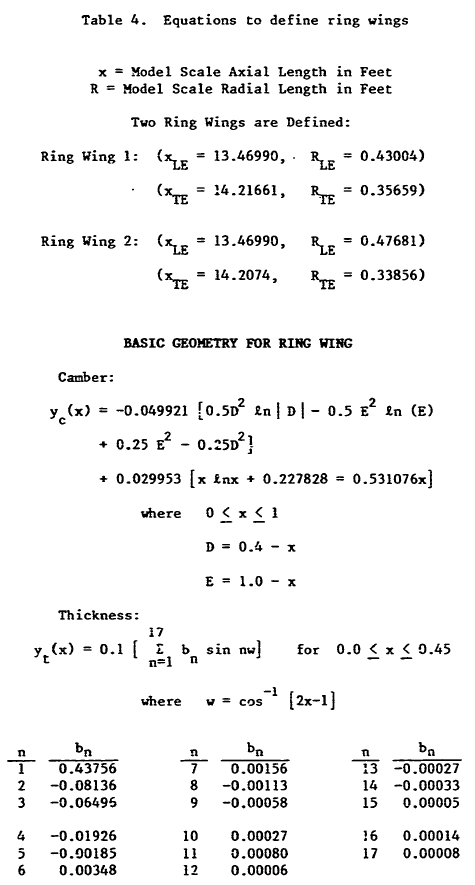

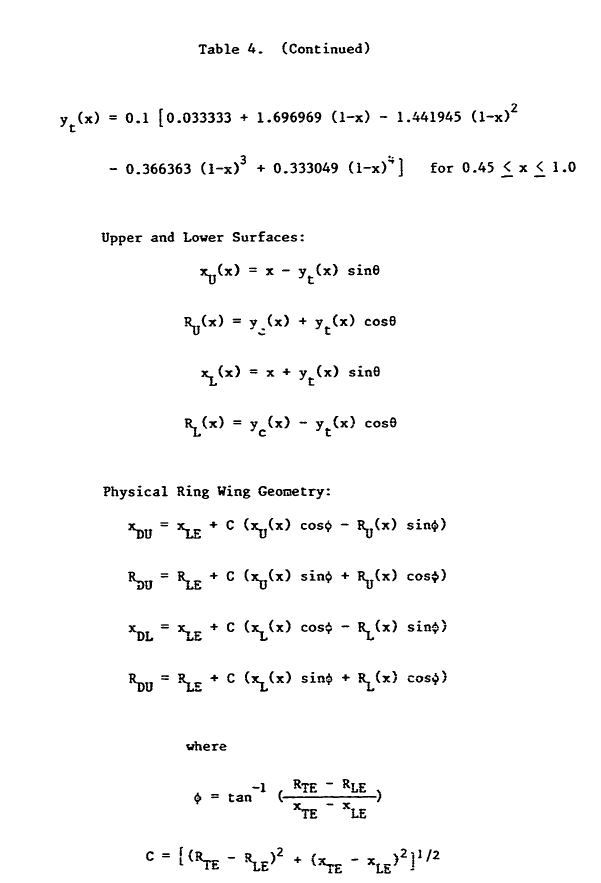

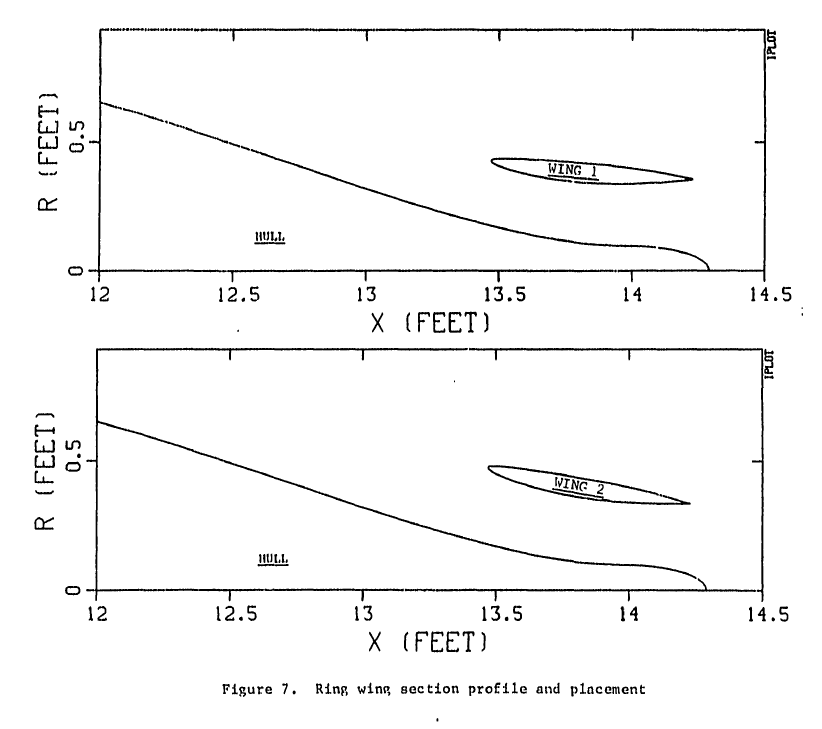

**Ringwing Selection **

RingWing Variable =1 or 2 to select Ring Wing

%ring wing selection
ringwing =1

ringwing = 1

if ringwing ==1
    xLE = 13.46990;
    xTE = 14.21661;
    RLE = 0.43004;
    RTE = 0.35659;
else
    xLE = 13.46990;
    xTE = 14.2074;
    RLE = 0.47681;
    RTE = 0.33856;
end

**Ring Wing Equations(1) Camber**

x=linspace(0, 1, 10000);
D=0.4 -x;
E=1.0-x;

% Camber function
Yc = -0.049921 .* (0.5 .* (D.^2) .* log(abs(D)) - 0.5 .* (E.^2) .* log(E) + 0.25 .* (E.^2) - 0.25 .* (D.^2) + 0.029953 .* (x .* log(x) + 0.227828 )); 
Yc(1)=Yc(2); %fix ln(0) = infinity

**Plot yc as a function of x**

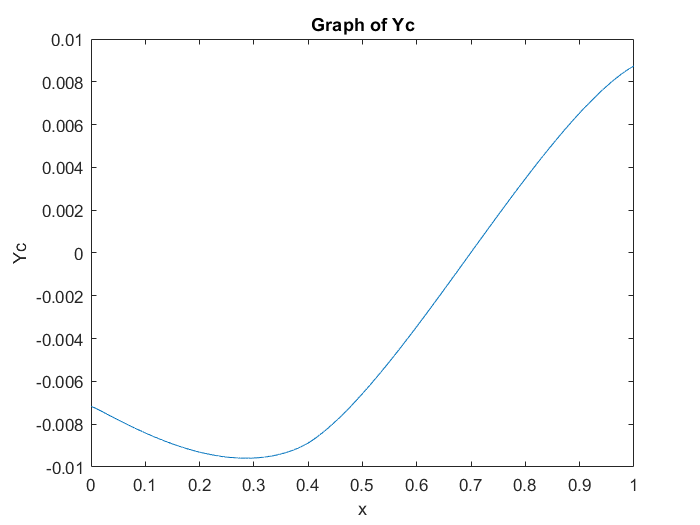

% Plot yc as a function of x
plot(x, Yc);
xlabel('x');
ylabel('Yc');
title('Graph of Yc');

**Ring Wing Equations(2) Thickness Part 1**

% Define the values of bn
bn = [0.43756, -0.08136, -0.06495, -0.01926, -0.00185, 0.00348, 0.00156, -0.00113, -0.00058, 0.00027, 0.00080, 0.00006, -0.00027, -0.00033, 0.00005, 0.00014, 0.00008];

% Define the value of w
Xmajor=linspace(0, 1, 10000); % Assuming x is a vector of 1000 values from 0 to 1
% Find the index where xmajor is equal to or greater than 0.45
index_045 = find(Xmajor >= 0.45, 1);

% Fill x1 with values from xmajor until the index where xmajor is 0.45
x1 = Xmajor(1:index_045);

w = acos(2 * x1 - 1);
% Calculate yt for each value of x
yt1 = zeros(size(x1));
for n = 1:17
    yt1 = yt1 + bn(n) * sin(n * w);
end
yt1 = 0.1 * yt1;

**Plot yt1 as a function of x**

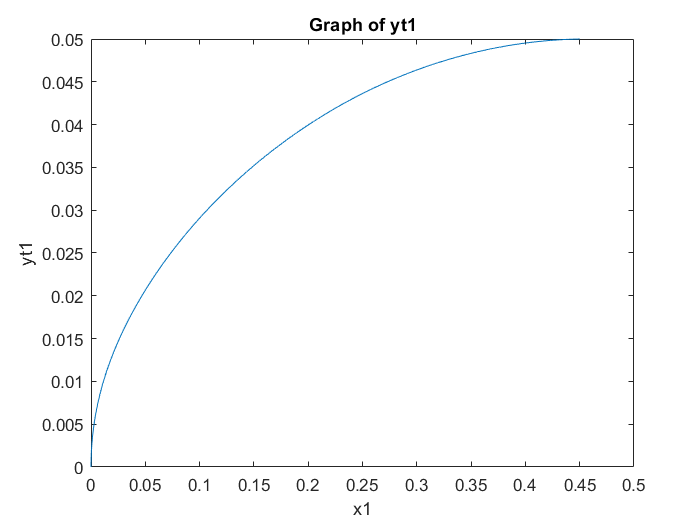

% Plot yt as a function of x
plot(x1, yt1);
xlabel('x1');
ylabel('yt1');
title('Graph of yt1');

**Ring Wing Equations(3) Thickness Part 2**

% Fill x2 with values from xmajor starting from the index where xmajor is 0.45
x2 = Xmajor(index_045+1:end);
% Calculate yt for each value of x
yt2 = zeros(size(x2));
yt2 = 0.1 .*(0.033333 + 1.696969.*(1-x2) -1.441945.*((1-x2).^2)-0.366363.*((1-x2).^3)+0.333049.*((1-x2).^4));

**Plot yt2 as a function of x**

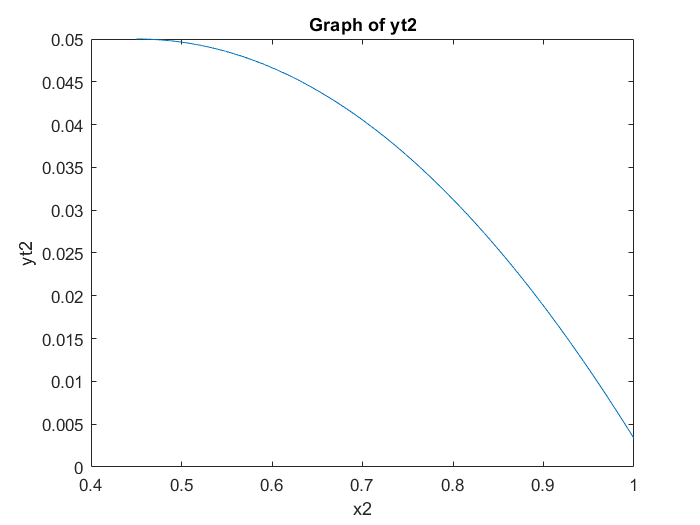

% Plot yt2 as a function of x
plot(x2, yt2);
xlabel('x2');
ylabel('yt2');
title('Graph of yt2');

x=[x1 x2];
yt=[yt1 yt2];

**Plot yt as a function of x**

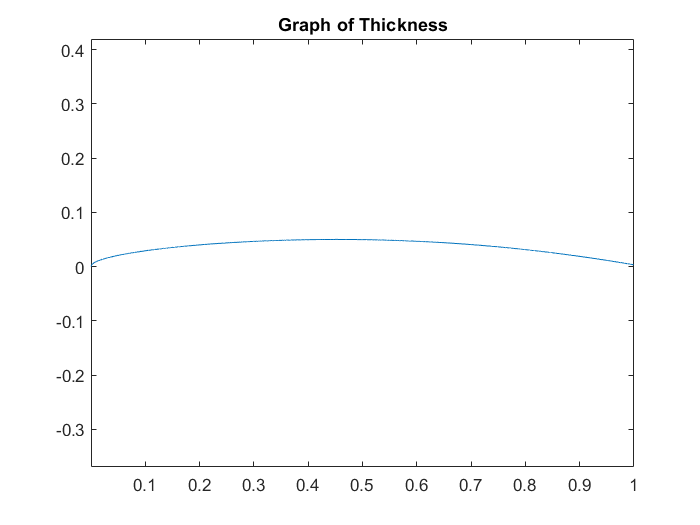

plot(x,yt)
title('Graph of Thickness');
axis equal

**Ring Wing Equations(4) xU,Ru**

divisionSeta=size(x,2);
stepseta=360/(divisionSeta-1);
seta=0:stepseta:360;
xU= x - yt .* sin(seta);
RU=Yc + yt .*cos(seta);

**Plot RU as a function of xU (Upper Surface)**

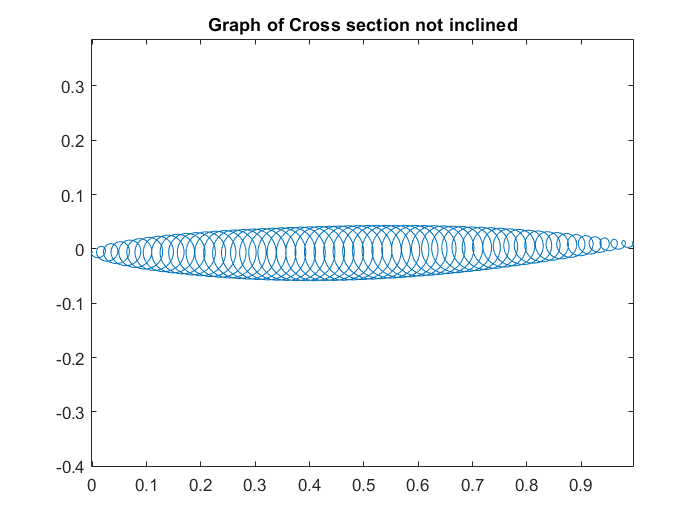

plot(xU,RU)
title('Graph of Cross section not inclined');
axis equal

**Ring Wing Equations(5) xL,RL**

xL=x +yt .*sin(seta);
RL=Yc - yt.*cos(seta);

**Plot RL as a function of xL (Lower Surface)**

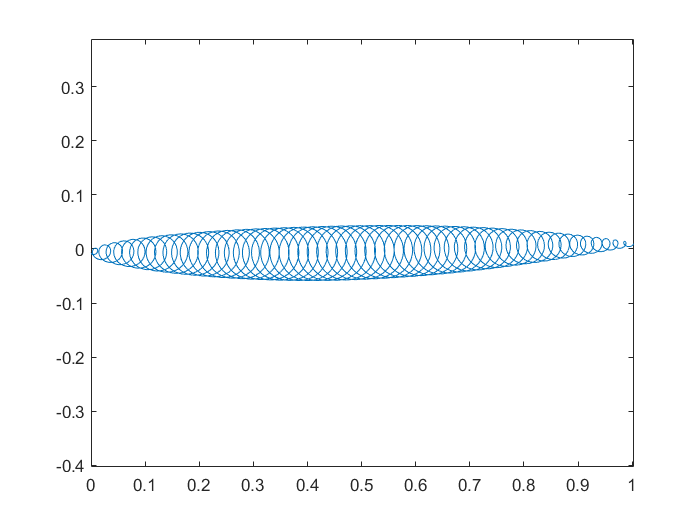

plot(xL,RL)
axis equal

**Ring Wing Equations(6) physical Ring wing geometry**

% physical Ring wing geometry 
phi=(RTE-RLE)/(xTE-xLE);
C=((RTE-RLE)^2+(xTE-xLE)^2)^0.5;

xDU = xLE + C*(xU*cos(phi)-RU*sin(phi)) ;
RDU = RLE + C*(xU*sin(phi)+RU*cos(phi));
xDL = xLE + C*(xL*cos(phi)-RL*sin(phi)) ;
RDL = RLE + C*(xL*sin(phi)+RL*cos(phi));

**physical Ring wing geometry Plot**

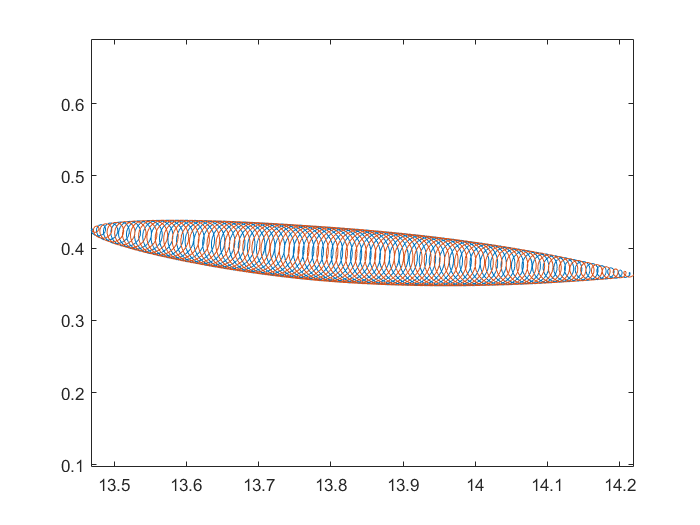

plot(xDU,RDU)
hold on 
plot(xDL,RDL)
axis equal
hold off

**2D Ring Wing Profile Points**

xD=[xDU xDL];
RD=[RDU RDL];
y0=zeros(size(xD));

**File Export**

% Save the  matrix as a CSV file
exportXYZtoCSV('XYZ_data_RingWing.csv', xD, y0, RD);

**RING WING STRUTS**

Strut supports are-necessary to mount the ring wings to the

hull. Four separate, identical struts are mounted equally-spaced

along the hull girth. The struts attach at the same axial

position on the hull, x=13.589 Ft

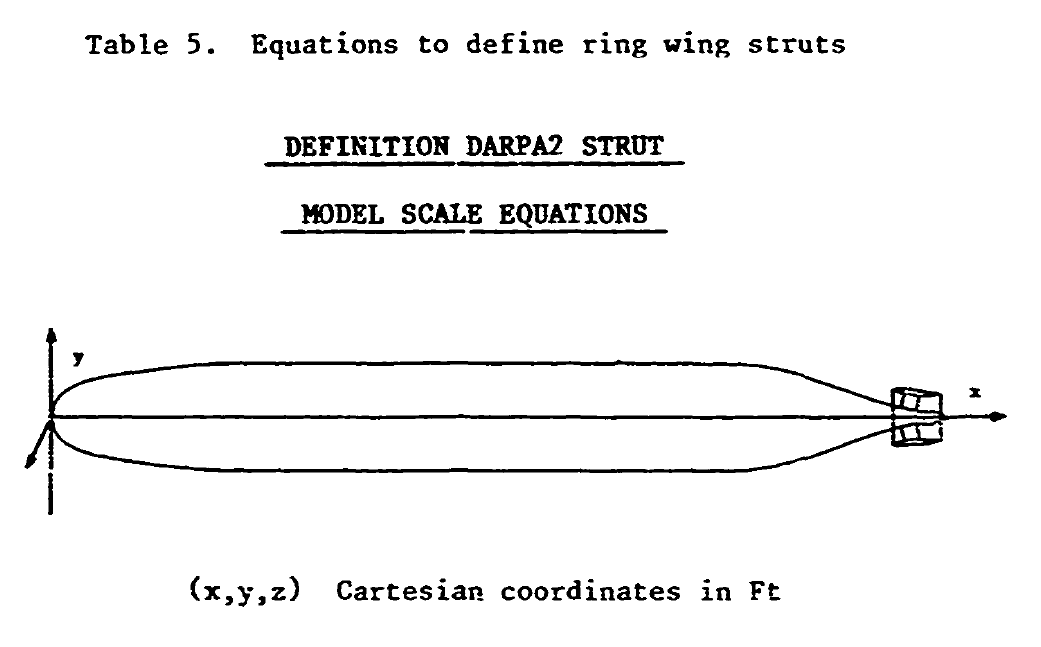

**Ring Wing Strut**

**Equations**

strutringinteractionfactor=0.05; % factor to make sure the strut pass through the ringwing lower surface without passing through the ring wing upper surface
y0 = R1:0.001:R2+strutringinteractionfactor;
y0=y0';
% Create x0
x0= 0.223221 * y0 + 13.556128;

% Define strut leading edge x1 and strut trailing edge x2
x1 = 13.589;
x2 = 13.83582;

% Define the range of x values
x = x1:0.001:x2;
% Repeat the rows of x to match the number of rows in x0
x_repeated = repmat(x, size(x0, 1), 1);

% Repeat the columns of x0 to match the number of columns in x
x0_repeated = repmat(x0, 1, numel(x));
x=x_repeated;
x0=x0_repeated;
% Calculate epsilon based on the given expression
epsilon = (x - x0(1)) / 0.243995;

% Calculate epsilon based on the given expression
epsilon = (x - x0(1)) / 0.243995; % Calculate epsilon using the first value of y0

% Replace any value less than 0 or greater than 1 with 0
epsilon(epsilon < 0 | epsilon > 1) = 0;

%Calculate x,y,z
x=x0+0.243995*epsilon;
y=y0-0.054465*epsilon;
z=0.15.*((0.29690.*sqrt(epsilon) - 0.12600.*epsilon - 0.35160.*epsilon.^2 + 0.28520.*epsilon.^3 - 0.10450 .*epsilon.^4));

**Plot Ring Wing Strut**

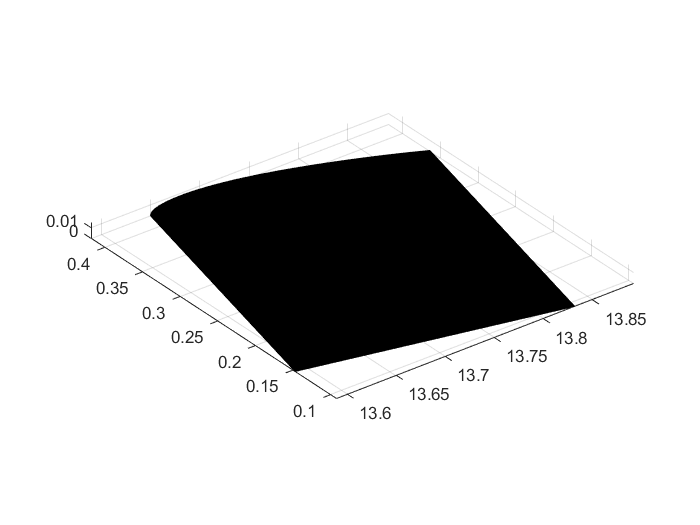

surf(x,y,z)
axis equal

**File Export**

% Save the  matrix as a CSV file
exportXYZtoCSV('XYZ_data_RingWingStrut.csv', x, z, y);